clear;

Define the function

f = @(x) sin(2*pi*x);

Plot the function

x_plot = 0:.01:1;
figure,
plot(x_plot, f(x_plot), 'g'),
xlabel("x"), ylabel("t"),
axis square;

Create some points

N = 10;
x = linspace(0, 1, N)';

Create a random Guassian distribution for add some noise to data

std = .3;
gaussian = normrnd(0, std, N, 1);

Evaluate target vector adding some noise

t = f(x) + gaussian;

Plot the target values above the function

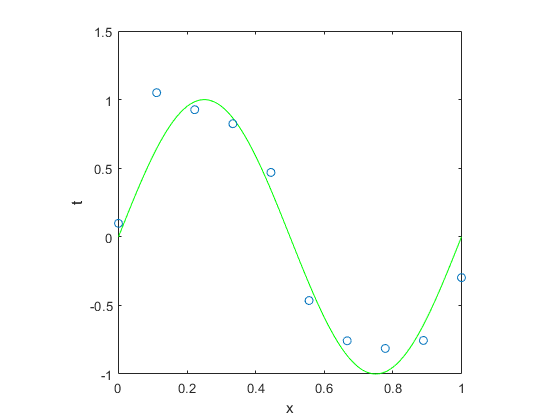

hold on,
plot(x, t, 'o');

Generate the model resolving the linear system generated from the partial derivatives of the polynomial with order M

M = 0:9;
W = linearRegression(M, x, t);

Creating the data

training = predict(10, W);
test = predict(100, W);

Calculating the RMS errors

gaussian = normrnd(0, std, 100, 1);
t_test = f(test.x) + gaussian; % Generate the target vector for test data
training.rms = zeros(length(W), 1);
test.rms = zeros(length(W), 1);
for wi=1:length(W)
    training.rms(wi) = rmse(training.y(:, wi), t);
    test.rms(wi) = rmse(test.y(:, wi), t_test);
end

Plots of polynomials having various orders M, shown as red curves, fitted to the data set shown in Figure 1.2

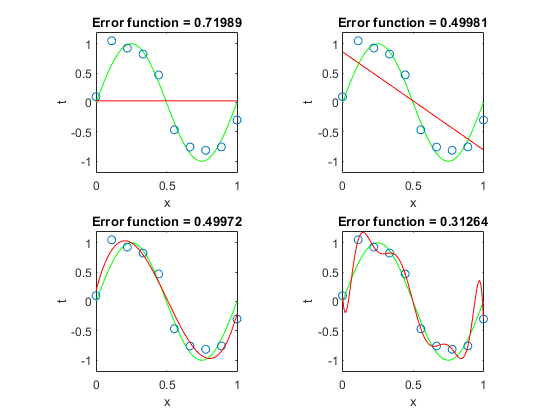

idx_w = [0 1 3 9] + 1;
figure,
for wi=1:length(idx_w)
    subplot(2, 2, wi),
    plot(x_plot, f(x_plot), 'g'),
    xlabel("x"), ylabel("t"),
    axis square;
    
    hold on,
    plot(x, t, 'o');
    
    hold on,
    plot(x_plot, pol(x_plot, W{idx_w(wi)}), 'r'),
    ylim([-1.2 1.2]);
    
    title(['Error function = ' num2str(test.rms(wi))]);
end

Plot a comparison of errors between test and training data to show the over-fitting problem:

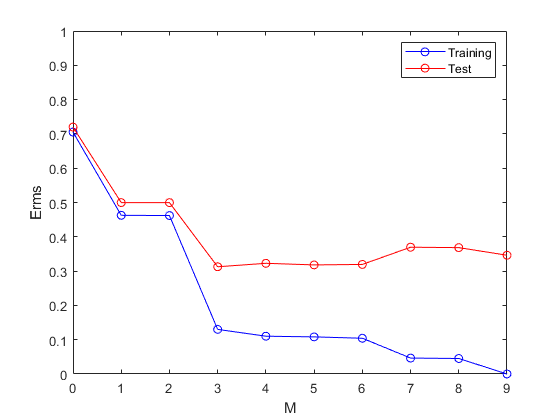

figure,
plot(M, training.rms, 'bO-'),
hold on,
plot(M, test.rms, 'rO-'),
axis([0 9 0 1]),
xlabel('M'), ylabel('Erms'),
legend({'Training', 'Test'});

Generate a table with w coefficients

wTable = table();
wTableVariables = zeros(length(W), length(M));
for wi=1:length(W)
    wTableVariables(wi, 1:length(W{wi})) = W{wi};
end
wTable.Variables = wTableVariables';

wTable.Properties.VariableNames = {'M_0', 'M_1', 'M_2', 'M_3', 'M_4', 'M_5', 'M_6', 'M_7', 'M_8', 'M_9'};
wTable

wTable = 10×10 table
      M_0         M_1        M_2        M_3        M_4        M_5        M_6        M_7         M_8          M_9    
    ________    _______    _______    _______    _______    _______    _______    ________    _______    ___________

    0.027918    0.86205    0.81944    0.18389    0.11029    0.12442    0.11372    0.098162    0.09753       0.098179
           0    -1.6683    -1.3807     9.0833     11.843     10.556     13.412      30.232     34.755         -32.99
           0          0    -0.2876    -27.866    -41.804    -31.073    -66.312     -343.85    -435.06         1129.7
           0          0          0     18.386     40.

Plots of the solutions obtained by minimizing the sum-of-squares error function using the M = 9 polynomial for N = 15 data points (left plot) and N = 100 data points (right plot). We see that increasing the size of the data set reduces the over-fitting problem.

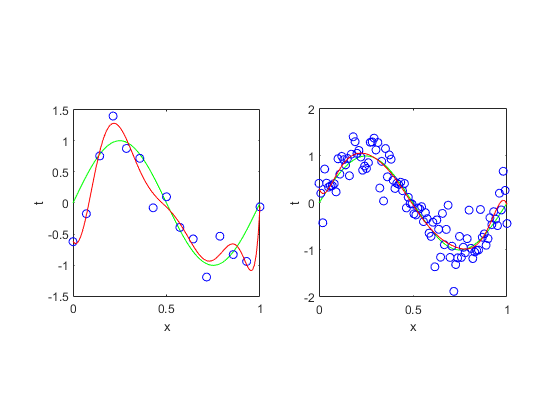

N = [15 100];
figure,
for ni=1:length(N)
    subplot(1, 2, ni),
    plot(x_plot, f(x_plot), 'g'),
    xlabel("x"), ylabel("t"),
    axis square;
    
    m = 9;
    n = N(ni);
    x = linspace(0, 1, n)';
    gaussian = normrnd(0, std, n, 1);
    t = f(x) + gaussian;
    
    hold on,
    plot(x, t, 'bo');
    
    w = linearRegression(m, x, t);
    
    hold on,
    plot(x_plot, pol(x_plot, w{1}), 'r');
end

One technique that is often used to control the over-fitting phenomenon in such cases is that of regularization, which involves adding a penalty term to the error function in order to discourage the coefficients from reaching large values. The simplest such penalty term takes the form of a sum of squares of all of the coefficients:

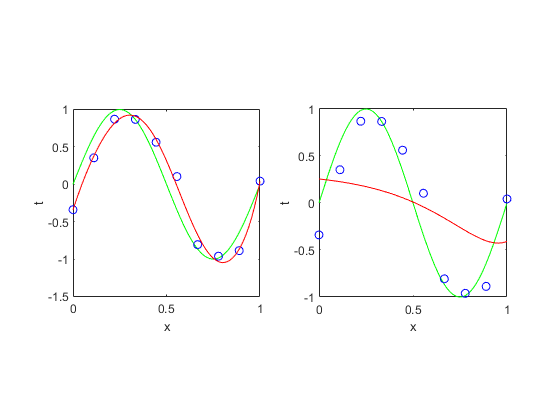

N = 10;
x = linspace(0, 1, N)';

std = .3;
gaussian = normrnd(0, std, N, 1);

t = f(x) + gaussian;

lambdas = [1e-8 1];
figure,
for li=1:length(lambdas)
    subplot(1, 2, li),
    plot(x_plot, f(x_plot), 'g'),
    xlabel("x"), ylabel("t"),
    axis square;
    
    hold on,
    plot(x, t, 'bo');
    
    m = 9;
    w = ridgeRegression(m, x, t, lambdas(li));
    
    hold on,
    plot(x_plot, pol(x_plot, w{1}), 'r');
end

Table of coefficients w* for M=9 polynomials with various values for the regulatrization parameter lambda.

wTable = table();
m = 9;
lambdas = [0 1e-8 1];
wTableVariables = zeros(length(lambdas), m+1);
for li=1:length(lambdas)
    w = ridgeRegression(m, x, t, lambdas(li));
    wTableVariables(li, 1:length(w{1})) = w{1};
end
wTable.Variables = wTableVariables';

wTable.Properties.VariableNames = {'ln_lambda_MinusInf', 'ln_lambda_Minus18', 'ln_lambda_0'};
wTable

wTable = 10×3 table
    ln_lambda_MinusInf    ln_lambda_Minus18    ln_lambda_0
    __________________    _________________    ___________

          -0.33946            -0.34318            0.25537 
            45.503              7.7346           -0.21333 
           -957.92             -12.214           -0.36145 
            9249.1              12.494           -0.29094 
            -46774             -34.865           -0.17932 
        1.3589e+05             -40.628          -0.073288 
       -2.3536e+05              124.86           0.016641 
        2.3973e+05               43.51             0.0902 
       -1.3232e+05             -186.08            0.14974 
             30498              85.565            0.19794 


Graph of the root-mean-square error versus ln (lambda) for the M = 9 polynomial.

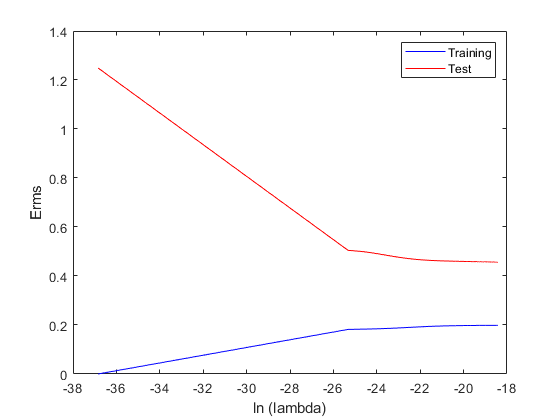

clear training test;
n = 10;
training.x = linspace(0, 1, n)';
training.gaussian = normrnd(0, std, n, 1);
training.t = f(training.x) + training.gaussian;

n = 100;
test.x = linspace(0, 1, n)';
test.gaussian = normrnd(0, std, n, 1);
test.t = f(test.x) + test.gaussian;

lambdas = 1e-16:1e-11:1e-8;
training.rms = zeros(length(lambdas), 1);
test.rms = zeros(length(lambdas), 1);
m = 9;
for li=1:length(lambdas)
    lambda = lambdas(li);
    w = ridgeRegression(m, training.x, training.t, lambda);
    
    training.y = pol(training.x, w{1});
    training.rms(li) = rmse(training.y, training.t);
    
    test.y = pol(test.x, w{1});
    test.rms(li) = rmse(test.y, test.t);
end

figure,
plot(log(lambdas), training.rms, 'b'),
hold on,
plot(log(lambdas), test.rms, 'r'),
xlabel('ln (lambda)'), ylabel('Erms'),
legend({'Training', 'Test'});